# Visual and Lidar Classification Fusion, Literate Programming Course

Created by Samantha Carley, 03/25/2023 This script takes LIDAR classifiers and visual classifiers and combines their output in order to produce a heightened context scene.

clear vars; clc; close all;

## Initializing parameters

Symbol for the chosen fusion function. The fusion methods are represented by the symbols:

1: Max

2: Min

3: Mean

fusionMethod = 3;

% We'll get some test samples to showcase visual detection and LiDAR
% detection on their own. The dataset used for this project implementation is an
% in-house dataset created using Unreal Engine 4 (a video game engine) and Carla, 
% an open-source simulator for autonomous driving. 
% Sample of visual imagery:
visSample = "F:\Datasets\UE4_LIDAR_VIS_APR22_TESTSET\test01\rgb\000001.png";
visSample = imread(visSample)

visSample = 540×960×3 uint8 array
visSample(:,:,1) =

   147   147   148   147   147   147   147   147   147   146   146   146   145   145   144   144   143   143   142   143   142   142   142   142   142   143   143   143   143   144   144   144   145   144   144   144   176   194   152   120   142   143   142   147   144   148   141   142   137   127   129   152   154   137   150   151   139   189   167   134   122   128   142   148   141   142   142   142   142   143   182   180   157   160   143   147   149   143   142   142   142   141   133   124   152   161   125   130   146   153   156   130   106   132   150   143   136   227   236   197   175   132    71   120   175   194   200   199   178   129   150   178   157   133   138   140   129   141   121   144   144   127   113   117   115   115   136   122    99   105   186   223   200   165   143   182   200   185   197   173   124   153   213   211   197   166   124   136   120    88   125   154   120    81    99    88   131   1

figure(1)
title("Camera View")
imshow(visSample)

% Sample of LiDAR imagery (same scene):
lidarSample = "F:\Datasets\UE4_LIDAR_VIS_APR22_TESTSET\test01\sem_lidar\PointClouds\000001.ply";
lidarSample = pcread(lidarSample)

lidarSample =   pointCloud with properties:

     Location: [248659×3 single]
        Count: 248659
      XLimits: [-95.4798 99.5879]
      YLimits: [-68.5966 63.0500]
      ZLimits: [-2.2018 11.9438]
        Color: []
       Normal: []
    Intensity: []


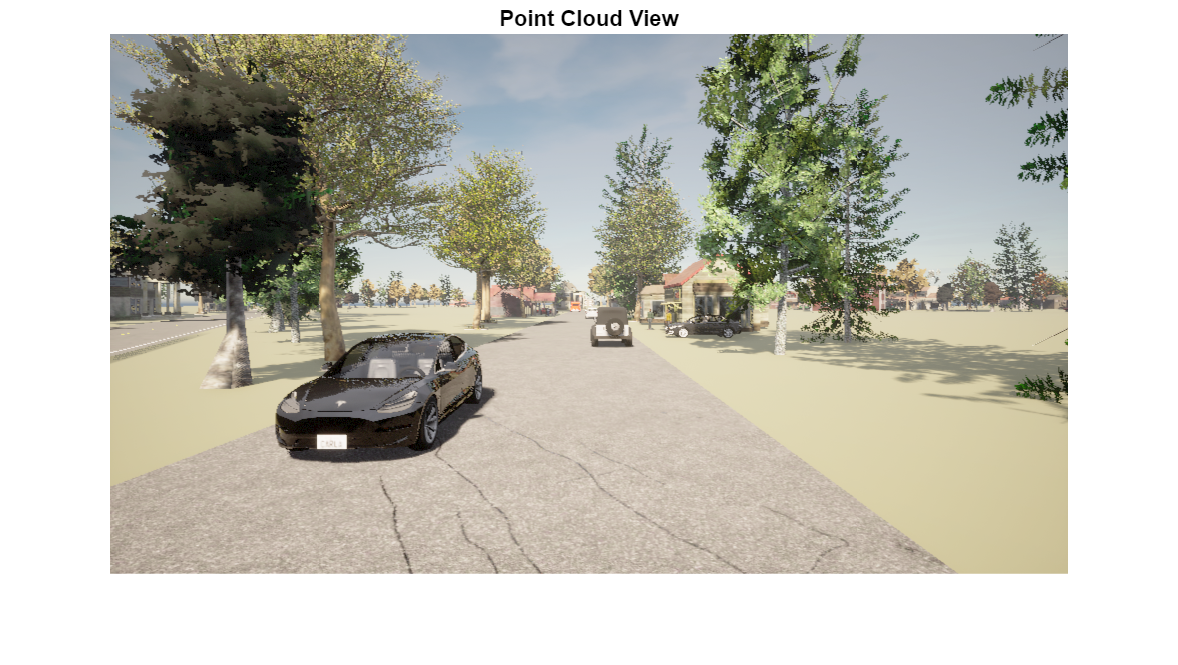

figure(2)
title("Point Cloud View")

ax = pcshow(lidarSample)

ax =   Axes (PointCloud) with properties:

             XLim: [-95.4798 99.5879]
             YLim: [-68.5966 63.0500]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


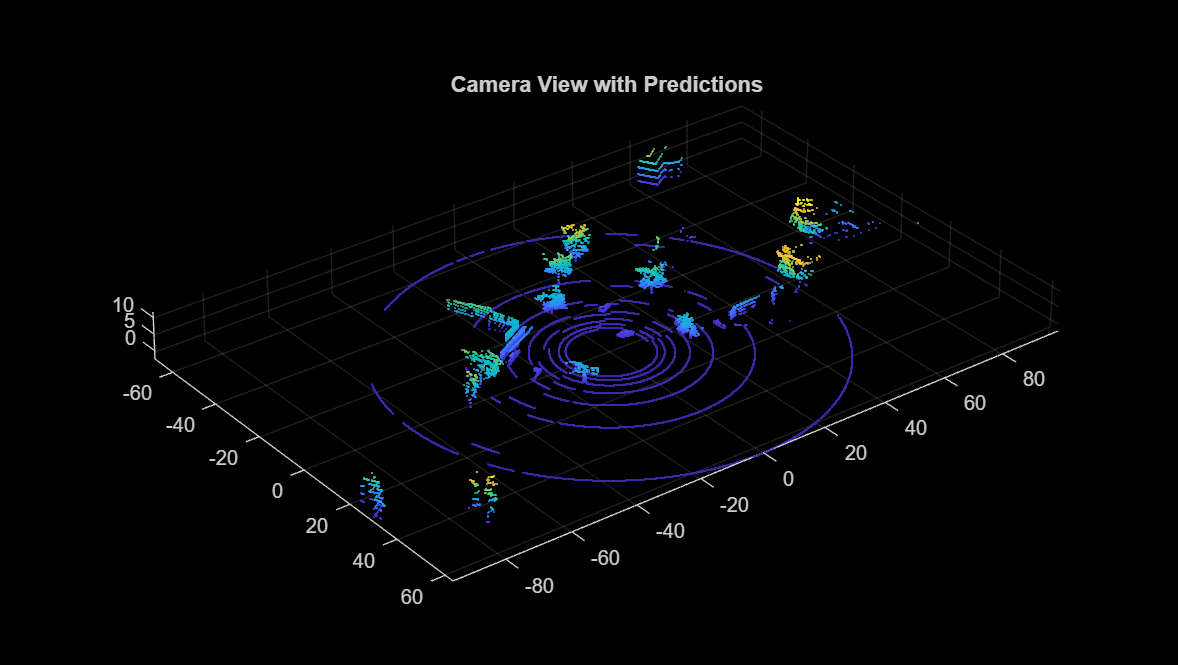

ax.YDir = 'reverse';

% Now, let's see what these scenes look like with object detection.
% We've got pre-detected predictions for the RGB space, so we will load that now:
load("F:\Datasets\UE4_LIDAR_VIS_APR22_TESTSET\VisPredictions\Vis_Detection_Res_test01.mat");
test01 = struct2table(Res);

% Next, we'll bring in the trained lidar object detection model.
% Lidar detection model, pretrained on PandaSet, and transfer learned on
% UE4 data:
load(['C:\Users\RDGSLSSC\Desktop\Projects\Private\ST CoVeR 6.3\' ...
    'LiDAR_Detection_Algs\Pretrained Models\yolov4-pandanetPretrained-UE4TransferLearned-corrected.mat']);

% Let's display detections for the visual scene:
visBboxes = ceil(test01.bboxes{1});
visScores = test01.scores{1};
visLabels = test01.labels{1};
visLabels(visLabels == 'car') = 'Vehicle';
visLabels(visLabels == 'truck') = 'Vehicle';
visLabels(visLabels == 'person') = 'Pedestrian';
visLabels(visLabels == 'motorbike') = 'Vehicle';
carLabels = {};
tmp = visScores(visLabels=='Vehicle');
for i = 1:height(visScores(visLabels=='Vehicle'))
    label = sprintf('Vehicle: %0.2f', tmp(i));
    carLabels{i} = label;
end
% Show visual solution
figure(3)
title("Camera View with Predictions")

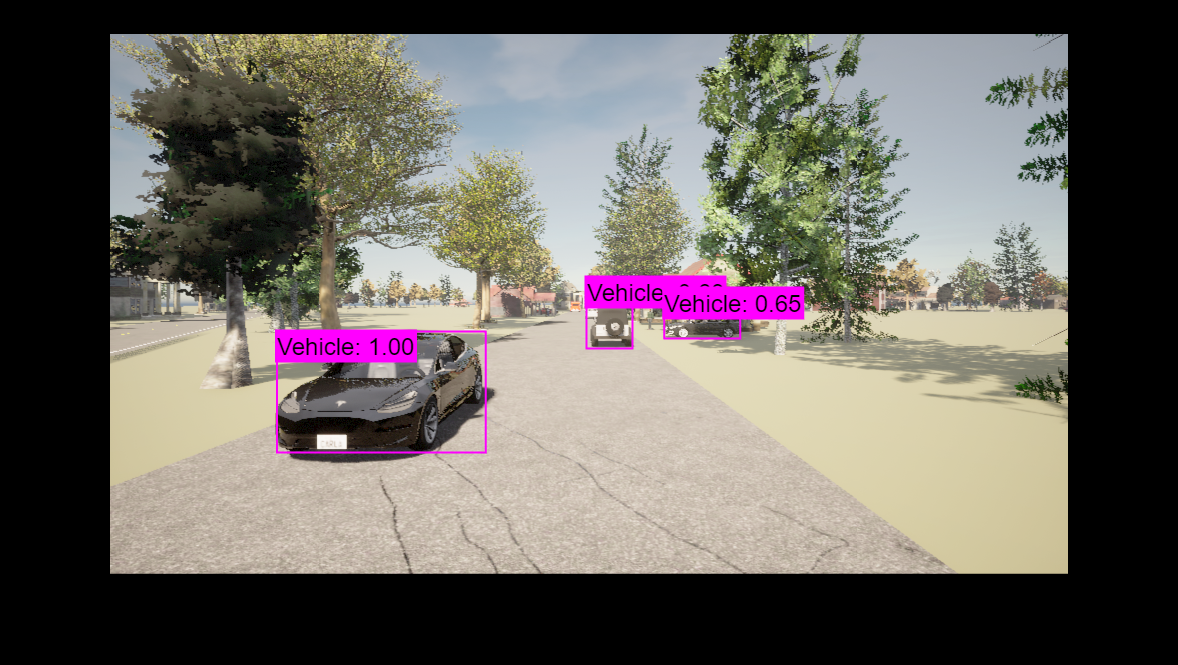

imshow(visSample)
showShape('rectangle',visBboxes(visLabels=='Vehicle',:),'Color','magenta','LineWidth',1,...
    'Label',carLabels,'LabelFontSize',10);
hold on;

showShape('rectangle',visBboxes(visLabels=='Pedestrian',:),'Color','yellow','LineWidth',1,...
    'Label','Pedestrian','LabelFontSize',10);

% Now we'll display detections for the lidar scene:
% These are predefined grid parameters.
gridParams = getGridParameters(); 
% Preprocess the lidar data into a format readable by the trained model.
% The model needs a "birds-eye-view" image in order to detect any objects
% within it.
if isempty(lidarSample.Intensity)
    lidarSample.Intensity = 256*ones(lidarSample.Count,1);
end
[processedImg,ptCloudOut] = preprocess(lidarSample,gridParams);
executionEnvironment = 'auto';
[bboxes,scores,labels] = detectComplexYOLOv4(net,processedImg,anchors,...
    classNames,executionEnvironment);
carLabels = {};
tmp = scores(labels=='Vehicle');
for i = 1:height(scores(labels=='Vehicle'))
    label = sprintf('Vehicle: %0.2f', tmp(i));
    carLabels{i} = label;
end
pedLabels = {};
tmp = scores(labels=='Pedestrian');
for i = 1:height(scores(labels=='Pedestrian'))
    label = sprintf('Pedestrian: %0.2f', tmp(i));
    pedLabels{i} = label;
end
% Show the detected bboxes.
figure
title("Point Cloud with Predictions")
ax = pcshow(lidarSample)

ax =   Axes (PointCloud) with properties:

             XLim: [-95.4798 99.5879]
             YLim: [-68.5966 63.0500]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


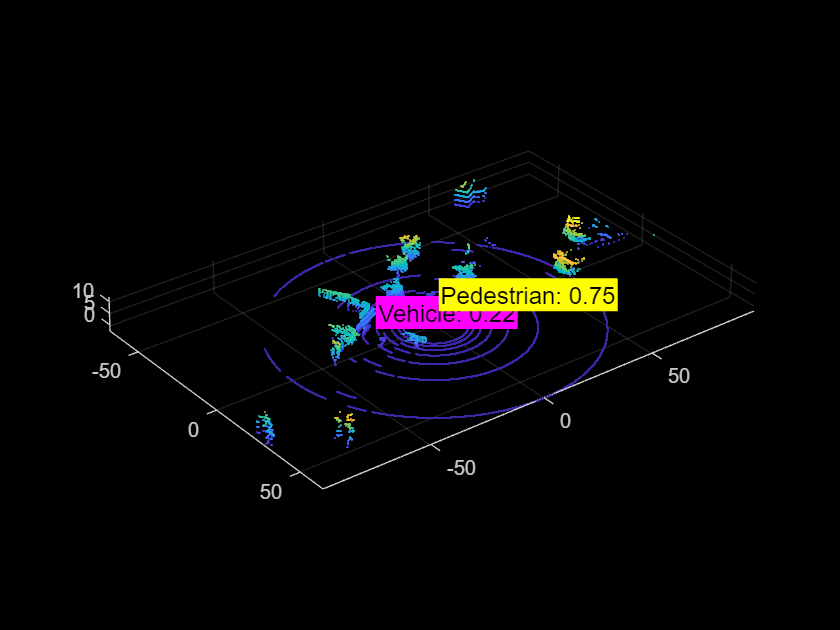

ax.YDir = 'reverse';
if ~isempty(bboxes)
    [ptCldOut,bboxCuboid] = transferbboxToPointCloud(bboxes,gridParams,ptCloudOut);
    showShape('cuboid',bboxCuboid(labels=='Vehicle',:),'Color','magenta','LineWidth',0.5,...
        'Label',carLabels,'LabelFontSize',10);
    hold on;
    showShape('cuboid',bboxCuboid(labels=='Pedestrian',:),'Color','yellow','LineWidth',0.5,...
        'Label',pedLabels,'LabelFontSize',10);
end


% Now that we see some detections in both the visual space and the LiDAR
% space, let's fuse them!

% To start, we need the visual camera information in order to crop out the
% scene of the LiDAR point cloud for comparing our two scenes. Right now,
% the point cloud is quite large, and does not represent the camera scene.
% This camera information is taken from the Carla documentation, as well as
% our own inferencing parameters between UE4 and Carla.
outView = [gridParams.xMin gridParams.xMax gridParams.yMin gridParams.yMax];
focalLength = [480 480];
R = [1 0 0; 0 1 0; 0 0 1];
t = [0; -0.5; 0];
camFOVH = 90;
% This function calculates the vertical field-of-view of the camera.
imgSize = [size(visSample,1) size(visSample,2)];
princPoint = [size(visSample,2)/2, size(visSample,1)/2];
camFOVV = 2*atand(tand(camFOVH/2)*imgSize(1)/imgSize(2));

% Filtering out lidar points that don't fall within camera view.
% Reorganizing the points in the point cloud in order to get the points
% that fall within view:
lidarPoints = [lidarSample.Location(:,2) -lidarSample.Location(:,3) lidarSample.Location(:,1)];
angleH = abs(atan2d(lidarPoints(:,1),lidarPoints(:,3)));
angleV = abs(atan2d(lidarPoints(:,2),lidarPoints(:,3)));
TF = angleH < (camFOVH/2) & ...
    angleV < (camFOVV/2);
lidarSample = pointCloud(lidarSample.Location(TF,:));
if isempty(lidarSample.Intensity)
    lidarSample.Intensity = 256*ones(lidarSample.Count,1);
end

% Displaying cropped point cloud with bboxes:
figure
title("Cropped Point Cloud with Predictions")
ax = pcshow(lidarSample)

ax =   Axes (PointCloud) with properties:

             XLim: [6.0096 99.5879]
             YLim: [-68.5966 44.5336]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


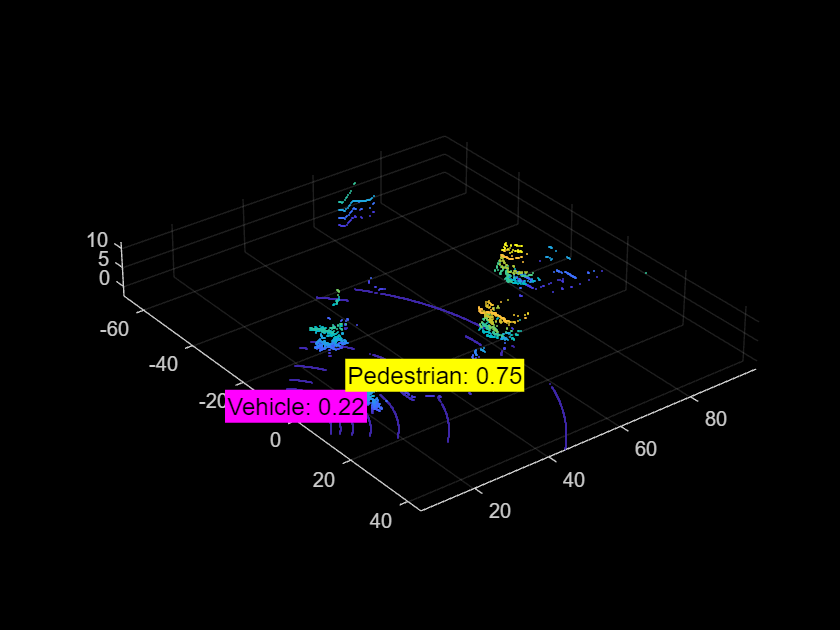

ax.YDir = 'reverse';
if ~isempty(bboxes)
    [ptCldOut,bboxCuboid] = transferbboxToPointCloud(bboxes,gridParams,ptCloudOut);
    showShape('cuboid',bboxCuboid(labels=='Vehicle',:),'Color','magenta','LineWidth',0.5,...
        'Label',carLabels,'LabelFontSize',10);
    hold on;
    showShape('cuboid',bboxCuboid(labels=='Pedestrian',:),'Color','yellow','LineWidth',0.5,...
        'Label',pedLabels,'LabelFontSize',10);
end


% Much better!
% Now, we can start fusing the results to merge the scene's predictions and
% create a complete picture.

% We will convert the 3D bounding boxes in the LiDAR space to 2D space, so
% that we may compare the detections.
intrinsics = cameraIntrinsics(focalLength,princPoint,imgSize);
K = intrinsics.IntrinsicMatrix';
% This function just converts the 3D bbox to a 2D bbox using the camera
% intrinsics. 
[bbox2D,validIdx] = LidarBboxTo2DBboxUE4(K,R,t,bboxCuboid,imgSize,outView,'Pred');
labels2D = labels(validIdx);
scores2D = scores(validIdx);
% Creating a table of the LiDAR data for easy grabbing.
lidarTable{1,1} = {bbox2D};
lidarTable{1,2} = {scores2D};
lidarTable{1,3} = {labels2D};

% Comparing the overlap of bounding boxes. If they overlap by 0.5 or above
% (standard for most object detection bboxes) then we will call that a
% match.
bboxOverlapLidar = bboxOverlapRatio(bbox2D,visBboxes);
condition = (bboxOverlapLidar > 0.5);
% Getting overlapping bboxes from the list of visual and Lidar detections.
forFusionVis = (any(condition,1))';
forFusionLidar = any(condition,2);

% Unique LiDAR detections.
howManyNonFusedLidar = size(bbox2D(~forFusionLidar),1)

howManyNonFusedLidar = 1

% Unique visual detections.
howManyNonFusedVis = size(visBboxes(~forFusionVis),1)

howManyNonFusedVis = 2

% Fused detections.
howManyFused = size(bbox2D(forFusionLidar),1) 

howManyFused = 1

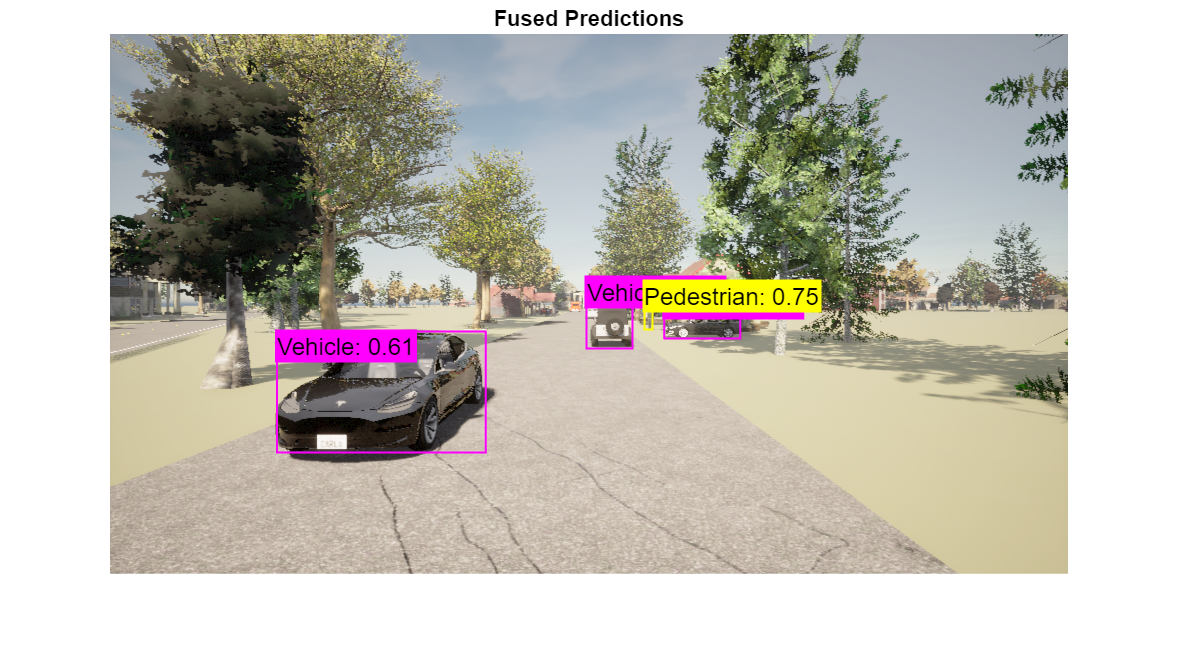

% Keeping track of nonfused bboxes and appending to an array...
nonFusedBboxes = [bbox2D(~forFusionLidar,:); visBboxes(~forFusionVis,:)];
nonFusedScores = [scores2D(~forFusionLidar,:); visScores(~forFusionVis,:)];
nonFusedLabels = [labels2D(~forFusionLidar,:); visLabels(~forFusionVis,:)];
% Find the fused prediction indices so we may compare their prediction
% scores.
indLidar = find(forFusionLidar);
indVis = find(forFusionVis);

% Now that we've got our unique and matching detections, we can fuse them
% using our chosen fusion function. Recall, the fusion functions we have
% implemented are: max, min, and mean.
totalBboxes = nonFusedBboxes;
totalScores = nonFusedScores;
totalLabels = nonFusedLabels;
fusedBboxes = [];
fusedScores = [];
fusedLabels = [];
if fusionMethod == 1
    % Find the max prediction score from the shared bboxes.
    [newScore,maxInd] = max([scores2D(forFusionLidar) visScores(forFusionVis)]);
    for k = 1:size(maxInd,1)
        % Here, we will set a score threshold of 0.3. If lower than that,
        % then we will assume that they are just false alarms and will discard them.
        if maxInd(k) == 1 && newScore >= 0.3
            % LiDAR is more confident. We'll take this one as the fused
            % result. 
            addBbox = bbox2D(indLidar,:);
            addScore = newScore(k);
            addLabel = labels2D(indLidar,:);
        elseif maxInd(k) == 2 && newScore >= 0.3
            % Visual is more confident. We'll take this one as the fused
            % result.
            addBbox = visBboxes(indVis,:);
            addScore = newScore(k);
            addLabel = visLabels(indVis,:);
        else
            addBbox = [];
            addScore = [];
            addLabel = [];
        end
        % Fused predictions are added to the total array of predictions.
        totalBboxes = [totalBboxes; addBbox];
        totalScores = [totalScores; addScore];
        totalLabels = [totalLabels; addLabel];
        fusedBboxes = [fusedBboxes; addBbox];
        fusedScores = [fusedScores; addScore];
        fusedLabels = [fusedLabels; addLabel];
        % Repeat loop for the amount of shared predictions.
    end
elseif fusionMethod == 2
    % Find the min prediction score from the shared bboxes.
    [newScore,minInd] = min([scores2D(forFusionLidar) visScores(forFusionVis)]);
    for k = 1:size(minInd,1)
        if minInd(k) == 2 && newScore >= 0.3
            % LiDAR is more confident
            addBbox = bbox2D(indLidar,:);
            addScore = newScore(k);
            addLabel = labels2D(indLidar,:);
        elseif minInd(k) == 1 && newScore >= 0.3
            % Visual is more confident
            addBbox = visBboxes(indVis,:);
            addScore = newScore(k);
            addLabel = visLabels(indVis,:);
        else
            addBbox = [];
            addScore = [];
            addLabel = [];
        end
        totalBboxes = [totalBboxes; addBbox];
        totalScores = [totalScores; addScore];
        totalLabels = [totalLabels; addLabel];
        fusedBboxes = [fusedBboxes; addBbox];
        fusedScores = [fusedScores; addScore];
        fusedLabels = [fusedLabels; addLabel];
    end
else
    % Find the min prediction score from the shared bboxes.
    [~,maxInd] = max([scores2D(forFusionLidar) visScores(forFusionVis)]);
    newScore = mean([scores2D(forFusionLidar) visScores(forFusionVis)]);
    % In the mean function, the max score's bounding bbox is taken, but the score
    % is averaged. 
    for k = 1:size(maxInd,2)
        if maxInd(k) == 1 && newScore >= 0.3
            % LiDAR is more confident
            addBbox = bbox2D(indLidar,:);
            addScore = newScore(k);
            addLabel = labels2D(indLidar,:);
        elseif maxInd(k) == 2 && newScore >= 0.3
            % Visual is more confident
            addBbox = visBboxes(indVis,:);
            addScore = newScore(k);
            addLabel = visLabels(indVis,:);
        else
            addBbox = [];
            addScore = [];
            addLabel = [];
        end
        totalBboxes = [totalBboxes; addBbox];
        totalScores = [totalScores; addScore];
        totalLabels = [totalLabels; addLabel];
        fusedBboxes = [fusedBboxes; addBbox];
        fusedScores = [fusedScores; addScore];
        fusedLabels = [fusedLabels; addLabel];
    end
end

% Show fused solution within the RGB space!
carLabels = {};
tmp = totalScores(totalLabels=='Vehicle');
for i = 1:height(totalScores(totalLabels=='Vehicle'))
    label = sprintf('Vehicle: %0.2f', tmp(i));
    carLabels{i} = label;
end
pedLabels = {};
tmp = totalScores(totalLabels=='Pedestrian');
for i = 1:height(totalScores(totalLabels=='Pedestrian'))
    label = sprintf('Pedestrian: %0.2f', tmp(i));
    pedLabels{i} = label;
end
figure
imshow(visSample)
title("Fused Predictions")
hold on;
showShape('rectangle',totalBboxes(totalLabels=='Vehicle',:),'Color','magenta','LineWidth',1,...
    'Label',carLabels,'LabelFontSize',8);
hold on;
showShape('rectangle',totalBboxes(totalLabels=='Pedestrian',:),'Color','yellow','LineWidth',1,...
    'Label',pedLabels,'LabelFontSize',8);

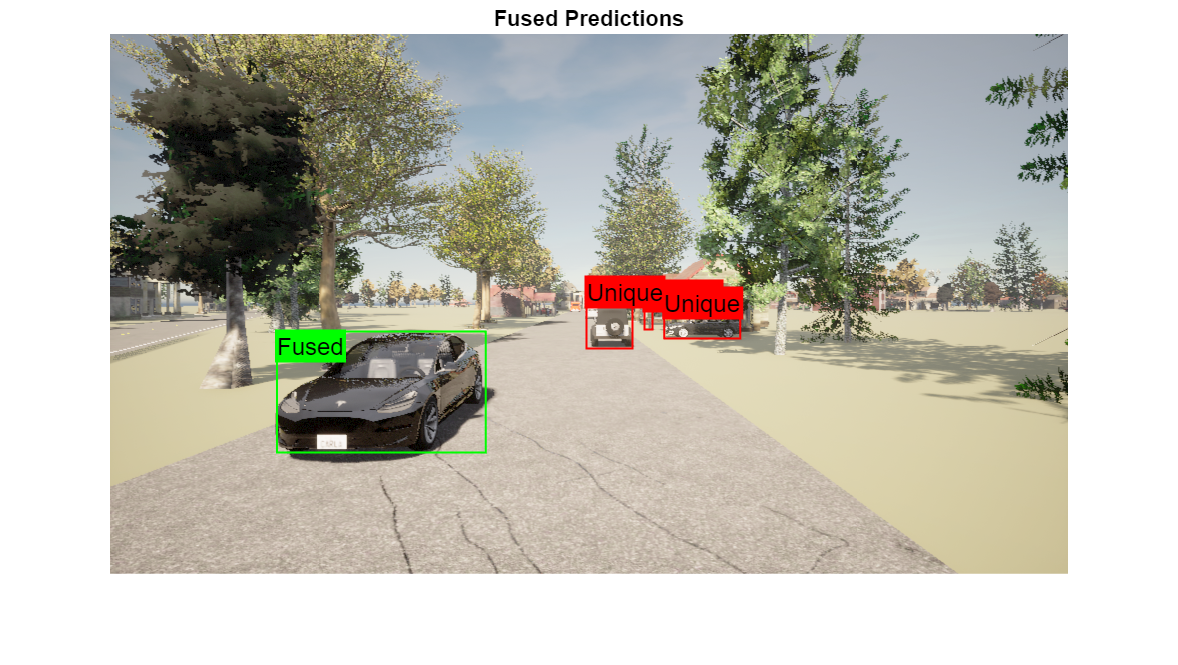


figure
imshow(visSample)
title("Fused Predictions")
hold on;
showShape('rectangle',fusedBboxes,'Color','green','LineWidth',1,'Label','Fused','LabelFontSize',10);
hold on;
showShape('rectangle',nonFusedBboxes,'Color','red','LineWidth',1,'Label','Unique','LabelFontSize',10);